r = @(x) 100*(x(2)-x(1)^2)^2 + (1-x(1))^2;
g = @(x) x(1)*(x(1) + 3)*(x(1) - 3)*(x(1) - 5) + x(2)*(x(2) + 3)*(x(2) - 3)*(x(2) - 5);
f = @(x) ((x(1))^2 - 100)*((x(1))^2 - 61) + ((x(2))^2 - 25)*((x(2))^2 - 16) - 15*cos(x(1)-(7/5))*cos(x(2)-(9/2));

Nvar = 2;
Nmax = 50;
errodf = 15e-3;
NPontosIniciais = 7;
x_values=[-11;-11]; y_values=[7;7];
lambda = 0.0005;

[Lista, LNit, Lopt] = steepest_descent_static(g, Nvar, Nmax, errodf, NPontosIniciais, x_values, y_values, lambda);

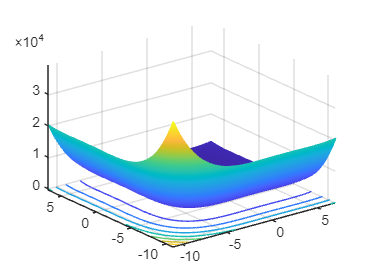

close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

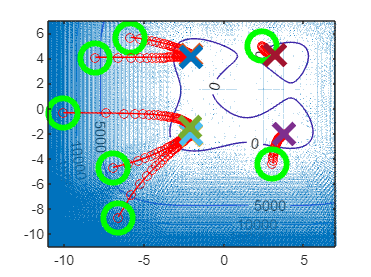


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

lambda = 0.000005;
 
[Lista, LNit, Lopt] = steepest_descent_static(r, Nvar, Nmax, errodf, NPontosIniciais, x_values, y_values, lambda);

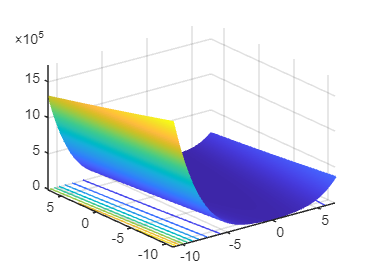

close all

nivelGraficos(r,x_values(1),y_values(1),x_values(2),y_values(2))

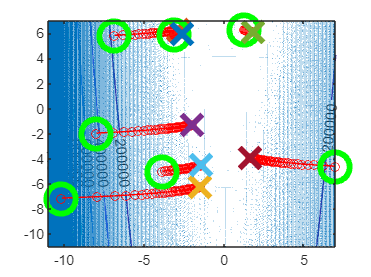


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

lambda = 0.0005;

[Lista, LNit, Lopt] = steepest_descent_static(f, Nvar, Nmax, errodf, NPontosIniciais, x_values, y_values, lambda);

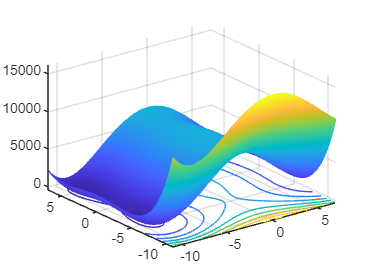

close all

nivelGraficos(f,x_values(1),y_values(1),x_values(2),y_values(2))

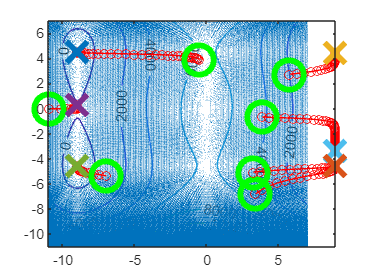


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off